
mouse_all=["111","123"]

mouse_all = 1×2 string array
    "111"    "123"


mouseID = ["111",
     "123"
    ]

mouseID = 2×1 string array
    "111"
    "123"



laser = ["1",
    "1"
    ]

laser = 2×1 string array
    "1"
    "1"


cd('/Users/pingchuanma/Desktop/ChenLab_Data/RvR/')



% running as 1, resting as 0
lft_all=[];
intensity_all=[];
animalID_all=[];
laser_all=[];
states_all=[];
speed_all=[];


for i=1:2
    mouse=find(mouse_all==mouseID(i));
    laserpower=str2num(laser(i));

    runningcsvfile=['runningDictsOutput',num2str(i-1),'.csv'];
    runningoutput=csvread(runningcsvfile,1,0);
    running_speed_csvfile=['speedOutput',num2str(i-1),'.csv'];
    running_speed_output=csvread(running_speed_csvfile,1,0);
    running_speed_output(:,1)=[];
    running_speed=[];
    for j=1:size(running_speed_output,1)
        running_speed(j,1)=max(running_speed_output(j,:));
    end
    j
    running_lft=runningoutput(:,8);
    running_intensity=runningoutput(:,2);
    n=length(running_lft)
    lft_all=[lft_all;running_lft];
    intensity_all=[intensity_all;running_intensity];
    animalID_all=[animalID_all;zeros(n,1)+mouse];
    laser_all=[laser_all;zeros(n,1)+laserpower];
    states_all=[states_all;zeros(n,1)+1];
    speed_all=[speed_all;running_speed];



    restingcsvfile=['baselineDictsOutput',num2str(i-1),'.csv'];
    restingoutput=csvread(restingcsvfile,1,0);
    resting_lft=restingoutput(:,8);
    resting_intensity=restingoutput(:,2);
    n=length(resting_lft);
    lft_all=[lft_all;resting_lft];
    intensity_all=[intensity_all;resting_intensity];
    animalID_all=[animalID_all;zeros(n,1)+mouse];
    laser_all=[laser_all;zeros(n,1)+laserpower];
    states_all=[states_all;zeros(n,1)];
    speed_all=[speed_all;zeros(n,1)];

   

    
end

j =     20


n =     20


j =     25


n =     25



intensity_all=intensity_all/100000;

lft_all_running=lft_all(find(states_all==1));
lft_all_resting=lft_all(find(states_all==0));

intensity_all_running=intensity_all(find(states_all==1));
intensity_all_resting=intensity_all(find(states_all==0));



lft1610=lft_all(find(animalID_all==1));
intensity1610=intensity_all(find(animalID_all==1));
speed1610=speed_all(find(animalID_all==1));
laser1610=laser_all(find(animalID_all==1));
states1610=states_all(find(animalID_all==1));

lft1610_1=lft1610(find(laser1610==1));
intensity1610_1=intensity1610(find(laser1610==1));
speed1610_1=speed1610(find(laser1610==1));
states1610_1=states1610(find(laser1610==1));
lft1610_1_running=lft1610_1(find(states1610_1==1));
lft1610_1_resting=lft1610_1(find(states1610_1==0));
intensity1610_1_running=intensity1610_1(find(states1610_1==1));
intensity1610_1_resting=intensity1610_1(find(states1610_1==0));


lft1610_2=lft1610(find(laser1610==3));
intensity1610_2=intensity1610(find(laser1610==3));
speed1610_2=speed1610(find(laser1610==3));
states1610_2=states1610(find(laser1610==3));
lft1610_2_running=lft1610_2(find(states1610_2==1));
lft1610_2_resting=lft1610_2(find(states1610_2==0));
intensity1610_2_running=intensity1610_2(find(states1610_2==1));
intensity1610_2_resting=intensity1610_2(find(states1610_2==0));

intensity_collection=[];
mouseID_collection=[];
laser_collection=[];
states_collection=[];

for i=1:2
    mouse=mouse_all(i)
    

    lft_mouse=lft_all(find(animalID_all==i));
    intensity_mouse=intensity_all(find(animalID_all==i));
    speed_mouse=speed_all(find(animalID_all==i));
    laser_mouse=laser_all(find(animalID_all==i));
    states_mouse=states_all(find(animalID_all==i));

    eval(['lft_',convertStringsToChars(mouse),'=lft_mouse;'])
    eval(['intensity_',convertStringsToChars(mouse),'=intensity_mouse;'])
    eval(['speed_',convertStringsToChars(mouse),'=speed_mouse;'])
    eval(['laser_',convertStringsToChars(mouse),'=laser_mouse;'])
    eval(['states_',convertStringsToChars(mouse),'=states_mouse;'])

    for j=1:3

        lft_mouse_laser=lft_mouse(find(laser_mouse==j));
        intensity_mouse_laser=intensity_mouse(find(laser_mouse==j));
        speed_mouse_laser=speed_mouse(find(laser_mouse==j));
        states_mouse_laser=states_mouse(find(laser_mouse==j));
        lft_mouse_laser_running=lft_mouse_laser(find(states_mouse_laser==1));
        lft_mouse_laser_resting=lft_mouse_laser(find(states_mouse_laser==0));
        intensity_mouse_laser_running=intensity_mouse_laser(find(states_mouse_laser==1));

        mouseID_collection=[mouseID_collection;str2num(mouse)];
        laser_collection=[laser_collection;j];
        states_collection=[states_collection;[1]];
        if isempty(intensity_mouse_laser_running)
            intensity_collection=[intensity_collection;[NaN]];
        else
            intensity_collection=[intensity_collection;mean(intensity_mouse_laser_running)];
        end

        intensity_mouse_laser_resting=intensity_mouse_laser(find(states_mouse_laser==0));

        mouseID_collection=[mouseID_collection;str2num(mouse)];
        laser_collection=[laser_collection;[j]];
        states_collection=[states_collection;[0]];
        if isempty(intensity_mouse_laser_resting)
            intensity_collection=[intensity_collection;[NaN]];
        else
            intensity_collection=[intensity_collection;mean(intensity_mouse_laser_resting)];
        end

        
        

        eval(['lft_',convertStringsToChars(mouse),'_',num2str(j),'=lft_mouse_laser;'])
        eval(['intensity_',convertStringsToChars(mouse),'_',num2str(j),'=intensity_mouse_laser;'])
        eval(['speed_',convertStringsToChars(mouse),'_',num2str(j),'=speed_mouse_laser;'])
        eval(['states_',convertStringsToChars(mouse),'_',num2str(j),'=states_mouse_laser;'])

        eval(['lft_',convertStringsToChars(mouse),'_',num2str(j),'_running','=lft_mouse_laser_running;'])
        eval(['lft_',convertStringsToChars(mouse),'_',num2str(j),'_resting','=lft_mouse_laser_resting;'])
        eval(['intensity_',convertStringsToChars(mouse),'_',num2str(j),'_running','=intensity_mouse_laser_running;'])
        eval(['intensity_',convertStringsToChars(mouse),'_',num2str(j),'_resting','=intensity_mouse_laser_resting;'])
    end

end

mouse = "111"

mouse = "123"


FYI=[mouseID_collection laser_collection states_collection intensity_collection];

        




figure1=figure;
figure1.Position=[10 10 500 400];

scatter(speed1610_1,lft1610_1,'filled')
hold on
scatter(speed1610_2,lft1610_2,'filled')
hold off
legend('Laser1','Laser2','FontSize',24)
xlabel('Speed (cm/s)')
xlim([-0.5 18])
xticks([0 5 10 15])
ylabel('Lifetime (ns)')
ylim([4.15 4.3])
yticks([4.15 4.2 4.25])
ax=gca

ax =   Axes with properties:

             XLim: [-0.5000 18]
             YLim: [4.1500 4.3000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax.FontSize=24

ax =   Axes with properties:

             XLim: [-0.5000 18]
             YLim: [4.1500 4.3000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1766 0.1695 0.7284 0.7555]
            Units: 'normalized'

  Show all properties


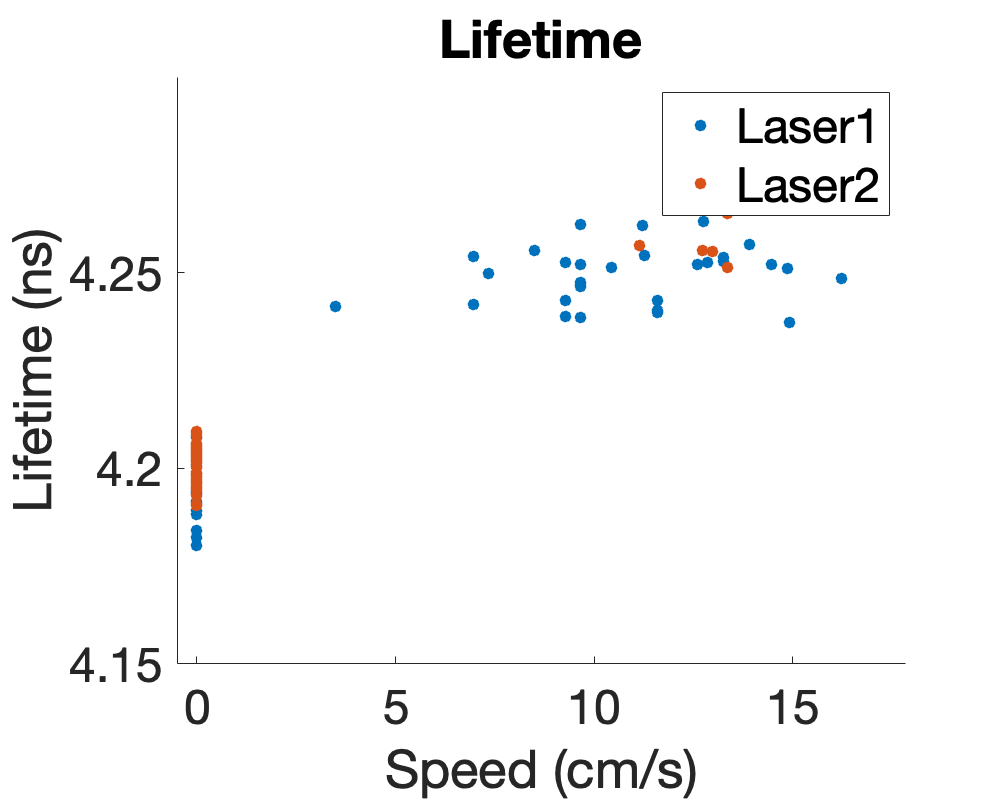

title('Lifetime')


figure2=figure;
figure2.Position=[10 10 500 400];

scatter(speed1610_1,intensity1610_1,'filled')
hold on
scatter(speed1610_2,intensity1610_2,'filled')
hold off
% legend('Laser1','Laser2')
xlabel('Speed (cm/s)')
xlim([-0.5 18])
xticks([0 5 10 15])
ylabel('Intensity')
ylim([2.50000 4.50000])
% yticks([250000 350000 450000])
ax=gca

ax =   Axes with properties:

             XLim: [-0.5000 18]
             YLim: [2.5000 4.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax.FontSize=24

ax =   Axes with properties:

             XLim: [-0.5000 18]
             YLim: [2.5000 4.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1496 0.1695 0.7554 0.7555]
            Units: 'normalized'

  Show all properties


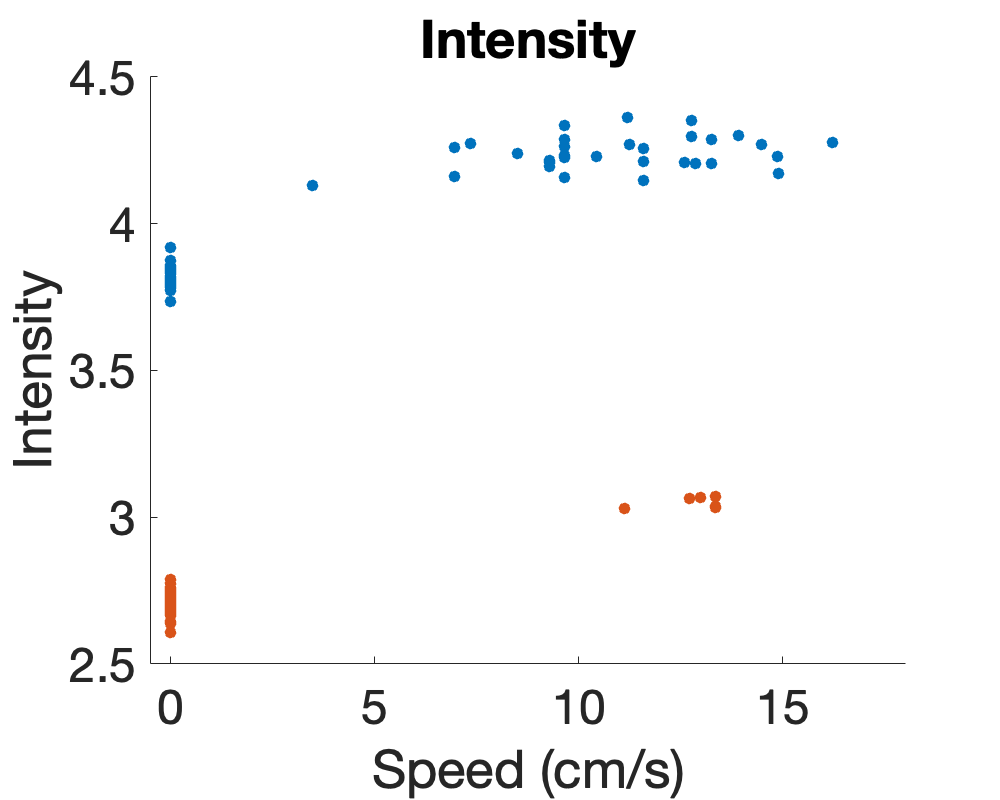

title('Intensity')

% Transform the categorical variables to dummy variables

states_all_categorical=categorical(states_all);
states_all_dv=dummyvar(states_all_categorical);
categories(states_all_categorical)

ans = 2×1 cell array
    {'0'}
    {'1'}



animalID_all_categorical=categorical(animalID_all);
animalID_all_dv=dummyvar(animalID_all_categorical);
categories(animalID_all_categorical)

ans = 7×1 cell array
    {'1'}
    {'2'}
    {'3'}
    {'4'}
    {'5'}
    {'6'}
    {'7'}



laser_all_categorical=categorical(laser_all);
laser_all_dv=dummyvar(laser_all_categorical);
categories(laser_all_categorical)

ans = 3×1 cell array
    {'1'}
    {'2'}
    {'3'}


% creat table for glm analysis, use the predictors as categorical
% By default, fitglm takes the last variable as the response variable and the others as the predictor variables
% If data is in a table or dataset array tbl, then, by default, 
% fitglm treats all categorical values, logical values, character arrays, 
% string arrays, and cell arrays of character vectors as categorical variables.

lft_tbl=table(states_all_categorical,animalID_all_categorical,laser_all_categorical,lft_all)

lft_tbl = 791×4 table
    states_all_categorical    animalID_all_categorical    laser_all_categorical    lft_all
    ______________________    ________________________    _____________________    _______

              1                          1                          1              4.23865
              1                          1                          1               4.2398
              1                          1                          1               4.2373
              1                          1                          1              4.23885
              1                          1                          1               4.2419
              1                          1                          1               4.2486
              1                          1                          1               4.2474
              1       

intensity_tbl=table(states_all_categorical,animalID_all_categorical,laser_all_categorical,intensity_all)

intensity_tbl = 791×4 table
    states_all_categorical    animalID_all_categorical    laser_all_categorical    intensity_all
    ______________________    ________________________    _____________________    _____________

              1                          1                          1                 4.22635   
              1                          1                          1                  4.2107   
              1                          1                          1                 4.17285   
              1                          1                          1                  4.2146   
              1                          1                          1                  4.2581   
              1                          1                          1                  4.2758   
              1                          1                 


% mdl1=fitglm(lft_tbl)
% mdl2=fitglm(intensity_tbl)

mdl1=stepwiseglm(lft_tbl,'constant','Criterion','adjrsquared')

1. Adding states_all_categorical, AdjRsquared = 0.66554
2. Adding laser_all_categorical, AdjRsquared = 0.85342
3. Adding animalID_all_categorical, AdjRsquared = 0.87891
4. Adding animalID_all_categorical:laser_all_categorical, AdjRsquared = 0.93193
5. Adding states_all_categorical:animalID_all_categorical, AdjRsquared = 0.93873


mdl1 = Generalized linear regression model:
    lft_all ~ 1 + states_all_categorical*animalID_all_categorical + animalID_all_categorical*laser_all_categorical
    Distribution = Normal

Estimated Coefficients:
                                                                 Estimate                  SE                   tStat                 pValue        
                                                           ____________________    ___________________    _________________    _____________________

    (Intercept)                                                4.19522950061907    0.00171011457925474     2453.18620840442                        0
    states_all_categorical_1                                 0.0553199504746177    0.00214643352966331     25.7729623163757    7.37606402576519e-106
    animalID_al

mdl2=stepwiseglm(intensity_tbl,'constant','Criterion','adjrsquared')

1. Adding animalID_all_categorical, AdjRsquared = 0.61526
2. Adding laser_all_categorical, AdjRsquared = 0.89121
3. Adding animalID_all_categorical:laser_all_categorical, AdjRsquared = 0.96356
4. Adding states_all_categorical, AdjRsquared = 0.9921
5. Adding states_all_categorical:animalID_all_categorical, AdjRsquared = 0.99656
6. Adding states_all_categorical:laser_all_categorical, AdjRsquared = 0.99731


mdl2 = Generalized linear regression model:
    intensity_all ~ 1 + states_all_categorical*animalID_all_categorical + states_all_categorical*laser_all_categorical + animalID_all_categorical*laser_all_categorical
    Distribution = Normal

Estimated Coefficients:
                                                                Estimate                  SE                  tStat                 pValue        
                                                           ___________________    __________________    _________________    _____________________

    (Intercept)                                               3.79986137502928    0.0129412987418087      293.62287749013                        0
    states_all_categorical_1                                 0.459754891075185    0.0165624787036365     27.7588215690348    

[B1, dev1, stats1]=mnrfit(lft_all, states_all_categorical)

B1 = 	1.0e+02 *

   7.174362109108005
  -1.696743332360426


dev1 =      2.497175223112708e+02


stats1 = struct with fields:
         beta: [2×1 double]
          dfe: 789
         sfit: 0.816370342142460
            s: 1
      estdisp: 0
         covb: [2×2 double]
    coeffcorr: [2×2 double]
           se: [2×1 double]
            t: [2×1 double]
            p: [2×1 double]
        resid: [791×2 double]
       residp: [791×2 double]
       residd: [791×1 double]


[A1, dlow1, dhi1]=mnrval(B1, lft_all, stats1)

A1 =    0.147555760125946   0.852444239874054
   0.124659477050281   0.875340522949719
   0.178749717845100   0.821250282154900
   0.143338176490322   0.856661823509678
   0.090681401667582   0.909318598332418
   0.031003488665814   0.968996511334186
   0.037740438278834   0.962259561721166
   0.025020086449343   0.974979913550657
   0.115692984280594   0.884307015719406
   0.009500649536631   0.990499350463369


dlow1 =    0.056269604957821   0.056269604957821
   0.051591306289634   0.051591306289634
   0.061548595486773   0.061548595486773
   0.055463582636511   0.055463582636511
   0.043056185478290   0.043056185478290
   0.020906880567299   0.020906880567299
   0.024095901152557   0.024095901152557
   0.017843720682716   0.017843720682716
   0.049541218577474   0.049541218577474
   0.008416474877252   0.008416474877252


dhi1 =    0.056269604957821   0.056269604957821
   0.051591306289634   0.051591306289634
   0.061548595486773   0.061548595486773
   0.055463582636511   0.055463582636511
   0.043056185478290   0.043056185478290
   0.020906880567299   0.020906880567299
   0.024095901152557   0.024095901152557
   0.017843720682716   0.017843720682716
   0.049541218577474   0.049541218577474
   0.008416474877252   0.008416474877252


[B2, dev2, stats2]=mnrfit(intensity_all, states_all_categorical)

B2 =   -0.123465151914018
  -0.065560767375396


dev2 =      1.070510436780465e+03


stats2 = struct with fields:
         beta: [2×1 double]
          dfe: 789
         sfit: 1.001103599874061
            s: 1
      estdisp: 0
         covb: [2×2 double]
    coeffcorr: [2×2 double]
           se: [2×1 double]
            t: [2×1 double]
            p: [2×1 double]
        resid: [791×2 double]
       residp: [791×2 double]
       residd: [791×1 double]


[A2, dlow2, dhi2]=mnrval(B2, intensity_all, stats2)

A2 =    0.401180707878799   0.598819292121201
   0.401427219950626   0.598572780049374
   0.402023622806559   0.597976377193441
   0.401365784157619   0.598634215842380
   0.400680749212589   0.599319250787411
   0.400402121762586   0.599597878237414
   0.400591014708857   0.599408985291143
   0.400424157748766   0.599575842251234
   0.400685472265778   0.599314527734222
   0.400959440895063   0.599040559104937


dlow2 =    0.038422107351606   0.038422107351606
   0.038247875013248   0.038247875013248
   0.037839649690276   0.037839649690276
   0.038291000117362   0.038291000117362
   0.038785094254865   0.038785094254865
   0.038992865697062   0.038992865697062
   0.038851585989393   0.038851585989393
   0.038976292939881   0.038976292939881
   0.038781605749647   0.038781605749647
   0.038581179774877   0.038581179774877


dhi2 =    0.038422107351606   0.038422107351606
   0.038247875013248   0.038247875013248
   0.037839649690276   0.037839649690276
   0.038291000117362   0.038291000117362
   0.038785094254865   0.038785094254865
   0.038992865697062   0.038992865697062
   0.038851585989393   0.038851585989393
   0.038976292939881   0.038976292939881
   0.038781605749647   0.038781605749647
   0.038581179774877   0.038581179774877


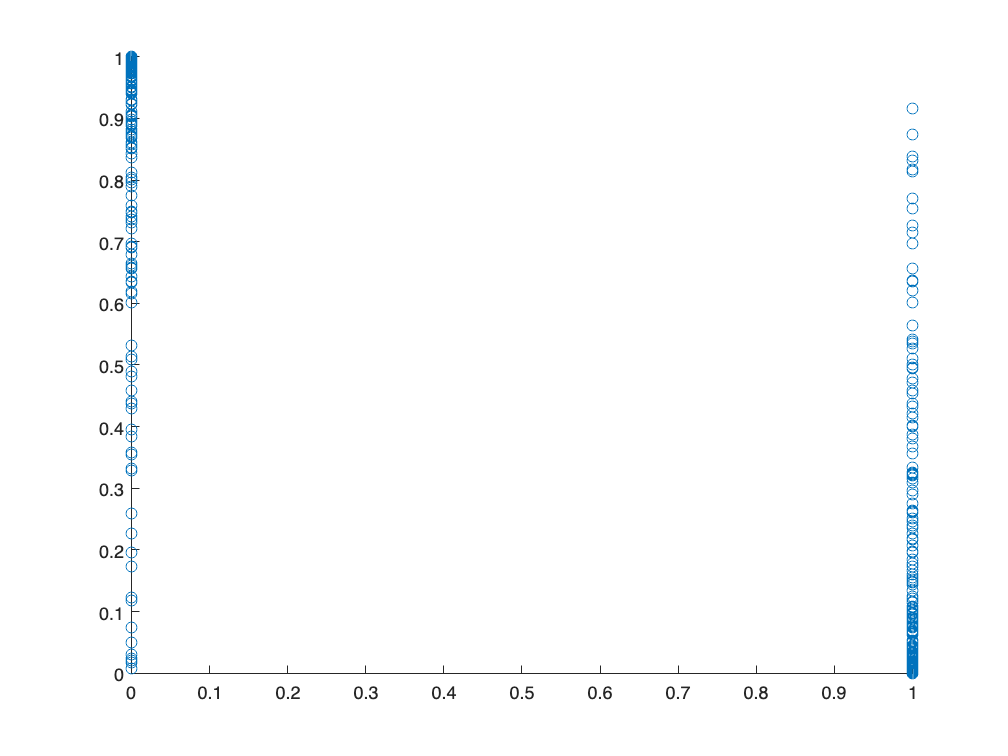

figure
scatter(states_all,A1(:,1))

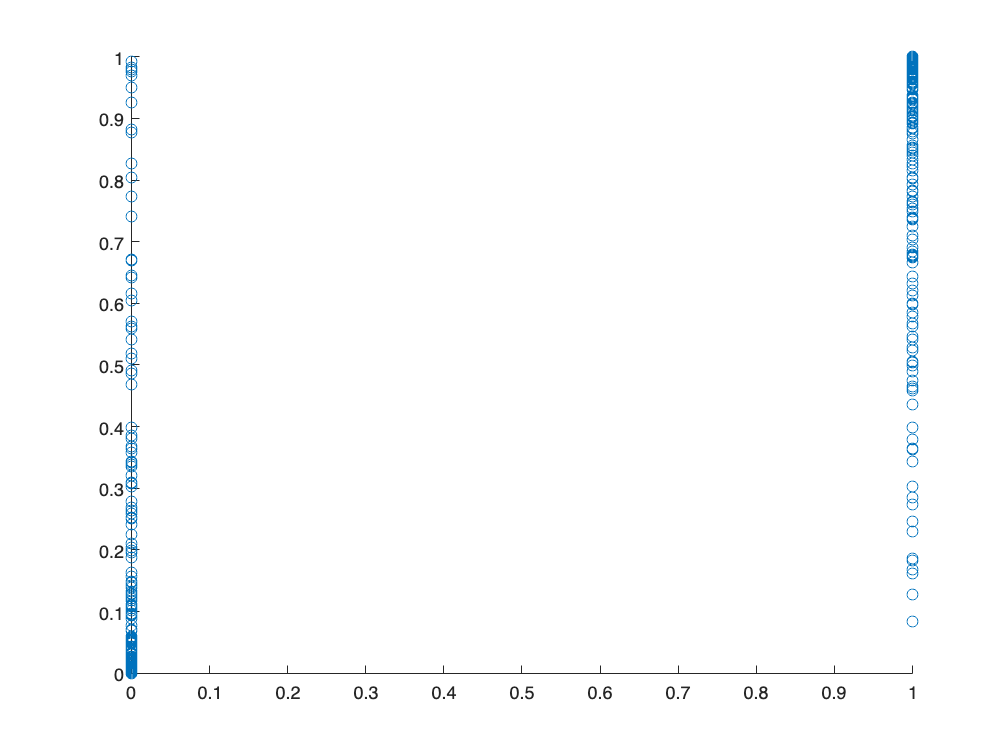

figure
scatter(states_all,A1(:,2))

A1_0=A1(find(states_all==0),1);
A1_1=A1(find(states_all==1),2);
A1_all=[A1_0;A1_1];
mean(A1_all)

ans =    0.904590056660606


std(A1_all)

ans =    0.194872933157909


mean(A1_0)

ans =    0.884249593279927


std(A1_0)

ans =    0.219494715964013


mean(A1_1)

ans =    0.918850252493082


std(A1_1)

ans =    0.174403845655489



length(find(A1_all>0.8))

ans =    665


length(find(A1_all>0.8))/length(A1_all)

ans =    0.840707964601770




figure
plot(A1_all)


A2_0=A2(find(states_all==0),1)

A2_0 =    0.408946667092454
   0.408373934681713
   0.407922578151280
   0.407305975489231
   0.407451590938503
   0.407410437097224
   0.407104198392477
   0.407291731373534
   0.407617802348589
   0.407051187644862


A2_1=A2(find(states_all==1),2)

A2_1 =    0.598819292121201
   0.598572780049374
   0.597976377193441
   0.598634215842380
   0.599319250787411
   0.599597878237414
   0.599408985291143
   0.599575842251234
   0.599314527734222
   0.599040559104937


A2_all=[A2_0;A2_1]

A2_all =    0.408946667092454
   0.408373934681713
   0.407922578151280
   0.407305975489231
   0.407451590938503
   0.407410437097224
   0.407104198392477
   0.407291731373534
   0.407617802348589
   0.407051187644862


mean(A2_all)

ans =    0.516315777375006



mean(A2_all)

ans =    0.516315777375006


std(A2_all)

ans =    0.088996232200177


mean(A2_0)

ans =    0.413199048931948


std(A2_0)

ans =    0.018437847332585


mean(A2_1)

ans =    0.588608365487774


std(A2_1)

ans =    0.023212200393834



length(find(A2_all>0.8))

ans =      0


length(find(A2_all>0.8))/length(A2_all)

ans =      0


[B1,dev1,stats1]=mnrfit([lft_all animalID_all laser_all], states_all_categorical)

B1 =   989.2577
 -235.5784
    0.2265
    4.0825


dev1 = 120.5628

stats1 = struct with fields:
         beta: [4×1 double]
          dfe: 787
         sfit: 2.2565
            s: 1
      estdisp: 0
         covb: [4×4 double]
    coeffcorr: [4×4 double]
           se: [4×1 double]
            t: [4×1 double]
            p: [4×1 double]
        resid: [791×2 double]
       residp: [791×2 double]
       residd: [791×1 double]


A1=mnrval(B1, [lft_all animalID_all laser_all])

A1 =     0.0069    0.9931
    0.0053    0.9947
    0.0095    0.9905
    0.0066    0.9934
    0.0032    0.9968
    0.0007    0.9993
    0.0009    0.9991
    0.0005    0.9995
    0.0047    0.9953
    0.0001    0.9999


[B2,dev2,stats2]=mnrfit([intensity_all animalID_all laser_all], states_all_categorical)

B2 =    -0.1221
    0.0571
   -0.2621
    0.4517


dev2 = 1.0162e+03

stats2 = struct with fields:
         beta: [4×1 double]
          dfe: 787
         sfit: 1.0010
            s: 1
      estdisp: 0
         covb: [4×4 double]
    coeffcorr: [4×4 double]
           se: [4×1 double]
            t: [4×1 double]
            p: [4×1 double]
        resid: [791×2 double]
       residp: [791×2 double]
       residd: [791×1 double]


A2=mnrval(B2, [intensity_all animalID_all laser_all])

A2 =     0.5766    0.4234
    0.5764    0.4236
    0.5758    0.4242
    0.5764    0.4236
    0.5770    0.4230
    0.5773    0.4227
    0.5771    0.4229
    0.5772    0.4228
    0.5770    0.4230
    0.5768    0.4232


A1_0=A1(find(states_all==0),1)

A1_0 =     0.9998
    0.9998
    0.9996
    0.9990
    0.9987
    0.9980
    0.9961
    0.9978
    0.9982
    0.9938


A1_1=A1(find(states_all==1),2)

A1_1 =     0.9931
    0.9947
    0.9905
    0.9934
    0.9968
    0.9993
    0.9991
    0.9995
    0.9953
    0.9999


A1_all=[A1_1;A1_1]

A1_all =     0.9931
    0.9947
    0.9905
    0.9934
    0.9968
    0.9993
    0.9991
    0.9995
    0.9953
    0.9999


mean(A1_all)

ans = 0.9643


A2_0=A2(find(states_all==0),1)

A2_0 =     0.5697
    0.5702
    0.5706
    0.5712
    0.5710
    0.5711
    0.5713
    0.5712
    0.5709
    0.5714


A2_1=A2(find(states_all==1),2)

A2_1 =     0.4234
    0.4236
    0.4242
    0.4236
    0.4230
    0.4227
    0.4229
    0.4228
    0.4230
    0.4232


A2_all=[A2_0;A2_1]

A2_all =     0.5697
    0.5702
    0.5706
    0.5712
    0.5710
    0.5711
    0.5713
    0.5712
    0.5709
    0.5714


mean(A2_all)

ans = 0.5488

% Trying to see whether numbers of these categorical variables matter
% I'm changing the running vs resting from 1 vs 0 to 1 vs 2.
states_all2=states_all;
states_all2(find(states_all2==1))=2;
states_all2_categorical=categorical(states_all2);
categories(states_all2_categorical)

ans = 2×1 cell array
    {'0'}
    {'2'}



lft_tbl=table(states_all2_categorical,animalID_all_categorical,laser_all_categorical,lft_all)
intensity_tbl=table(states_all2_categorical,animalID_all_categorical,laser_all_categorical,intensity_all)

mdl3=fitglm(lft_tbl)

mdl3 = Generalized linear regression model:
    lft_all ~ 1 + states_all2_categorical + animalID_all_categorical + laser_all_categorical
    Distribution = Normal

Estimated Coefficients:
                                   Estimate         SE         tStat        pValue   
                                  ___________    _________    ________    ___________

    (Intercept)                        4.1841    0.0015296      2735.4              0
    states_all2_categorical_2        0.062211    0.0010479      59.364    1.0164e-291
    animalID_all_categorical_2     -0.0023871    0.0022338     -1.0686        0.28557
    animalID_all_categorical_3      0.0032213     0.002025      1.5908        0.11207
    animalID_all_categorical_4     -0.0076694    0.0022985     -3.3367    

mdl4=fitglm(intensity_tbl)

mdl4 = Generalized linear regression model:
    intensity_all ~ 1 + states_all2_categorical + animalID_all_categorical + laser_all_categorical
    Distribution = Normal

Estimated Coefficients:
                                  Estimate       SE        tStat       pValue   
                                  ________    ________    _______    ___________

    (Intercept)                    4.0996     0.044256     92.634              0
    states_all2_categorical_2     0.49131      0.03032     16.204     3.9823e-51
    animalID_all_categorical_2    -2.3717      0.06463    -36.696    3.8998e-172
    animalID_all_categorical_3     1.3163     0.058588     22.467     1.2911e-86
    animalID_all_categorical_4    -1.4695     0.066501    -22.097     2.0051e-84
    anima

states_all2=states_all;
states_all2(find(states_all2==0))=2;
states_all2_categorical=categorical(states_all2);
categories(states_all2_categorical)

ans = 2×1 cell array
    {'1'}
    {'2'}



lft_tbl=table(states_all2_categorical,animalID_all_categorical,laser_all_categorical,lft_all)
intensity_tbl=table(states_all2_categorical,animalID_all_categorical,laser_all_categorical,intensity_all)

mdl5=fitglm(lft_tbl)

mdl5 = Generalized linear regression model:
    lft_all ~ 1 + states_all2_categorical + animalID_all_categorical + laser_all_categorical
    Distribution = Normal

Estimated Coefficients:
                                   Estimate         SE         tStat        pValue   
                                  ___________    _________    ________    ___________

    (Intercept)                        4.2463    0.0015484      2742.5              0
    states_all2_categorical_2       -0.062211    0.0010479     -59.364    1.0164e-291
    animalID_all_categorical_2     -0.0023871    0.0022338     -1.0686        0.28557
    animalID_all_categorical_3      0.0032213     0.002025      1.5908        0.11207
    animalID_all_categorical_4     -0.0076694    0.0022985     -3.3367    

mdl6=fitglm(intensity_tbl)

mdl6 = Generalized linear regression model:
    intensity_all ~ 1 + states_all2_categorical + animalID_all_categorical + laser_all_categorical
    Distribution = Normal

Estimated Coefficients:
                                  Estimate       SE        tStat       pValue   
                                  ________    ________    _______    ___________

    (Intercept)                     4.5909    0.044798     102.48              0
    states_all2_categorical_2     -0.49131     0.03032    -16.204     3.9823e-51
    animalID_all_categorical_2     -2.3717     0.06463    -36.696    3.8998e-172
    animalID_all_categorical_3      1.3163    0.058588     22.467     1.2911e-86
    animalID_all_categorical_4     -1.4695    0.066501    -22.097     2.0051e-84
    anima

save('RvRanalysis.mat')